# Trying to generate PSRN and SAM

12/1/2022

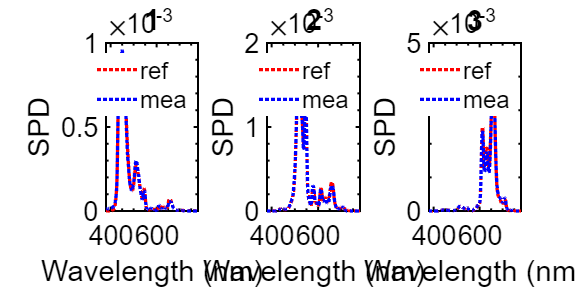


clf; analyze_one_display('compare_RGB_primaries_result_nec','NEC');

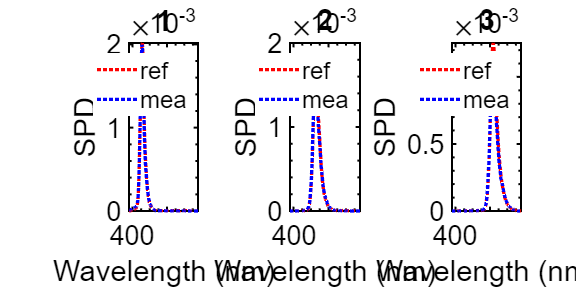

clf; analyze_one_display('compare_RGB_primaries_result_hp','HP')
clf; analyze_one_display('compare_RGB_primaries_result_rift','RIFT')

function analyze_one_display (fn_mat, dispname)
load(fn_mat)

clf

hfig = figure;

set(hfig, 'Units', 'inches', ...
    'Color', [1,1,1]);

set(hfig, ...
    'Units'              , 'inches',...
    'Position'           , [1 1 6 3]);

my_compare_psnr_sam(s_predicted_b,mea_b,1);
my_compare_psnr_sam(s_predicted_g,mea_g,2);
my_compare_psnr_sam(s_predicted_r,mea_r,3);

end


## PSRN and SAM

%
%
%
function [psnr_val sam_deg] = my_compare_psnr_sam (speC1, speC2, no)

s1 = speC1.amplitude;
s2 = speC2.amplitude;
psnr_val = psnr(s1,s2);
sam_deg = rad2deg(sam(s1,s2));

s1 = speC1.amplitude;
s2 = speC2.amplitude;

haxis = subplot(1,3,no);

hold on
plot(380:780,s1,'r:')
plot(380:780,s2,'b:')
%axis([380 780 0 5e-3])
tstr = sprintf('%.2f, %.2f',psnr_val,sam_deg);
title(no)
xlabel('Wavelength (nm)')
ylabel('SPD')
legend('ref','mea')

PlotBeautify(haxis);

end

